# Algorithms for Discrete Optimal Transport

The following code aims to solve


$$\min K(\gamma)$$


    subject to


$$\sum_{j} \gamma_{i,j} = m_i $$
    
$$\forall i \in [M],$$



$$\sum_{i} \gamma_{i,j} = n_j$$
    
$$\forall j \in [N],$$



$$\gamma_{i,j} \geq 0$$
    
$$\forall i\in [M], j\in [N].$$


Here $K$ is defined as $K(\gamma) = c:\gamma = \sum_{i,j} c_{i,j} \gamma_{i,j}$, with $c\geq 0$ a cost matrix.

## Preliminaries

To solve this problem, we will implement a Forward–Backward algorithm. In order to be able to state this algorithm, let us identify the simplex $C_1^m$ as the set


$$C_1^m := \left\{ x \in \mathbb{R}^{M\times N}: \, \sum_{j \in N} x_{i,j} = m_i \,\,\, \forall i \in [M] \wedge x\geq 0 \right\}$$


and similarly the simplex $C_2^n$ as the set


$$C_2^n := \left\{ x \in \mathbb{R}^{M\times N}: \, \sum_{i \in M} x_{i,j} = n_j \,\,\, \forall j \in [N] \wedge x\geq 0 \right\}.$$


We denote the intersection of these sets as $C = C_1^m \cap C_2^n$ and its indicator function as $\imath_C.$

Moreover, notice that $K$is a continuously differentiable function (as it is a lineal operator) and its derivative at any point in $\mathbb{R}^{M\times N}$ is the constant $\nabla K = c$. Matrix $c$ has a Lipschitz constant $\mu$ which coincides with its operator norm. Depending on the complexity (dimension) of the problem, we can use the spectral norm (largest singular value of $c$) or the simpler $\ell_1$ and $\ell_\infty$ induced norms.

## Algorithm statement

Now we present the Forward-backward algorithm which aims to minimise $K$satisfying the constraints imposed by sets $C_1^m$ and $C_2^n$:

- Let $\varepsilon \in (0,\mu^{-1}).$

- Let $x_0 \in \mathbb{R}^{M\times N}$.

- **For **$k \in \{1, 2, \ldots\}$`:`

-     Select $\gamma_k \in [\varepsilon, 2\mu^{-1} - \varepsilon]$.

-     Define $y_k := x_k - \gamma_k c$.

-     Select $\lambda_k \in [\varepsilon, 1]$.

-     Define $x_{k+1} := x_k + \lambda_k ( \mathrm{prox}_{\gamma_k \,\cdot \, \imath_C}(y_k) - x_k )$.

The proximal operator $\mathrm{prox}_{\gamma_k \,\cdot \, \imath_C}(y_k)$ present in step 7 will be computed using the next algorithm.

## Proximal operator

The proximal operator of the indicator function $\imath_C$ is computed taking the following steps:

- Let $\varepsilon \in (0,1).$

- Let $k = 0.$

- Select $v_{1,k} \in C_1^m$ and $v_{2,k} \in C_2^n.$

- **do while** $z\notin C$:

-     Define $z_k := y - \frac{1}{2}( v_{1,k} + v_{2,k} )$.

-     Select $\theta_k \in [\varepsilon, 2-\varepsilon]$.

-     
$$v_{1,k+1} := v_{1,k} + \theta_k \left( z_k  - \mathrm{proj}_{C_1^m} ( \theta_k^{-1} v_{1,k} + z_k ) \right)$$


-     
$$v_{2,k+1} := v_{2,k} + \theta_k \left( z_k  - \mathrm{proj}_{C_2^n} ( \theta_k^{-1} v_{2,k} + z_k ) \right)$$


-     
$$k = k+1.$$


- Return $z = \mathrm{prox}_{\imath_C}(y)$.

The projection operators $\mathrm{proj}_{C_1^m}$ and $\mathrm{proj}_{C_2^n}$ are computed using the function `project_simplex` from the Proximity Operator Repository. Likewise, the function `indicator_simplex` will be used in step 4 as an stopping criteria.

# Numerical experimentation

The purpose of this section is to experimentate with one large instance which its optimal value is known. In all our calculations, we will discretise number of points from$\mu = \mathcal{U}(0,1)$ and 

$\nu = \mathcal{U}(1,2)$ as a regular evenly-spaced interval. That is, we have $M = N.$ We only use the squared euclidean distance. Here, the optimal solution is $K(x) = 1$.

obj_fb = cell2mat(struct2cell(load('Results/jj5/FB-Objjj=5.mat')));

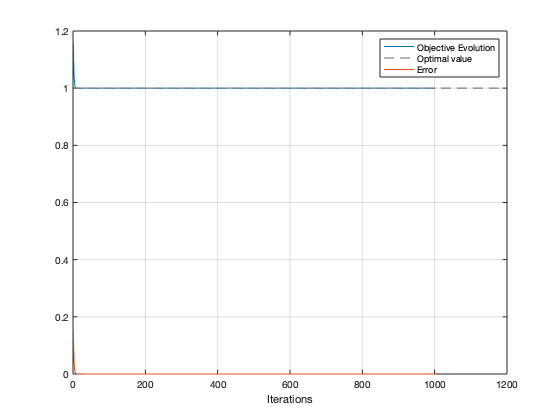

plot(obj_fb)
hold on
yline(1.0, '--');
hold on
plot( abs(1.0-obj_fb) );
legend('Objective Evolution','Optimal value','Error')
hold off 

grid on
xlabel('Iterations')

# Forward–Backward with backtracking

Show results

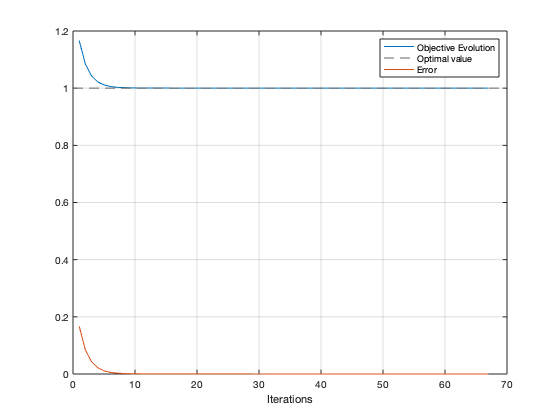

obj_fbb = cell2mat(struct2cell(load('Results/jj5/FBbacktrack-Obj.mat')));
plot(obj_fbb)
hold on
yline(1.0, '--');
hold on
plot( abs(1.0-obj_fbb) );
legend('Objective Evolution','Optimal value','Error')
grid on
xlabel('Iterations')
hold off 

# FISTA

## Algorithm statement

Now we present an adapted FISTA to minimise $K$satisfying the constraints imposed by sets $C_1^m$ and $C_2^n$:

- Let $\varepsilon \in (0,\mu^{-1}).$

- Let $x_0 \in \mathbb{R}^{M\times N}$, $z_0 = x_0$, $t_0 = 1$.

- Select $\mu > 0$.

- **For **$k \in \{1, 2, \ldots\}$`:`

-     Define $y_{k} := z_{k-1} - \mu^{-1} c$.

-     Define $x_{k} := \mathrm{prox}_{\mu^{-1} \,\cdot \, \imath_C}(y_{k}) =  \mathrm{prox}_{\imath_C}(y_{k})$.

-     Define $t_k := \frac{1 + \sqrt{1 + 4 t^2_{k-1}} }{2}$.

-     Define $\lambda_k := 1 + \frac{t_{k-1}-1}{t_k }$

-     Define $z_k := x_{k-1} + \lambda_k ( x_{k} - x_{k-1} )$.

obj_fi = cell2mat(struct2cell(load('Results/jj5/Fista-Objjj=5.mat')));

Show results

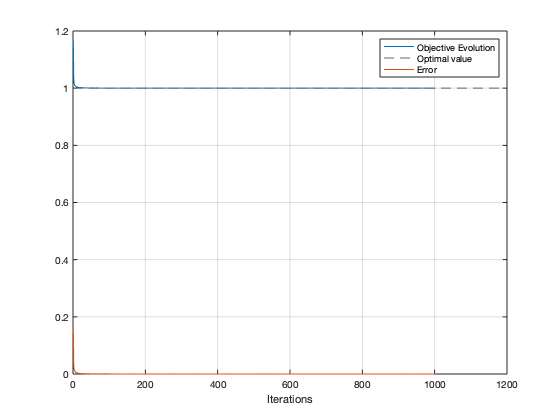

plot(obj_fi)
hold on
yline(1.0, '--');
hold on
plot( abs(1.0-obj_fi) );
legend('Objective Evolution','Optimal value','Error')
grid on
xlabel('Iterations')
hold off 

%plotGamma(m,n,x_fi,M,N)

# FISTA with backtracking

Show results

%plot(obj_fib)
%hold on
%yline(1.0, '--');
%hold on
%plot( abs(1.0-obj_fib) );
%legend('Objective Evolution','Optimal value','Error')
%grid on
%xlabel('Iterations')
%hold off 


# Primal dual

obj_pd = cell2mat(struct2cell(load('Results/jj5/Primaldual-Objjj=5.mat')));

Show results

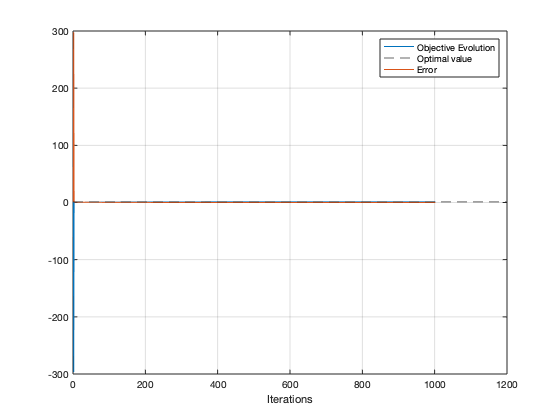

plot(obj_pd)
hold on
yline(1.0, '--');
hold on
plot( abs(1.0-obj_pd) );
legend('Objective Evolution','Optimal value','Error')
hold off 

grid on
xlabel('Iterations')

# Linear programming

%plot(fval)
%hold on
%yline(1.0, '--');
%hold on
%plot( abs(1.0- fval) );
%legend('Objective Evolution','Optimal value','Error')
%hold off 

%grid on
%xlabel('Iterations')

Display result

# Entropic Regularisation

obj_er = cell2mat(struct2cell(load('Results/jj5/Entropicreg-Objjj=5.mat')));

Show results

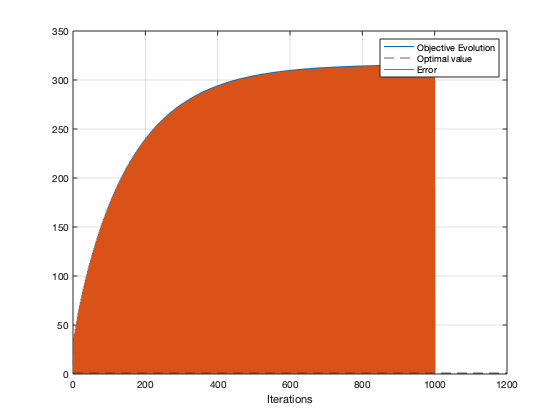

plot(obj_er)
hold on
yline(1.0, '--');
hold on
plot( abs(1.0-obj_er) );
legend('Objective Evolution','Optimal value','Error')
grid on
xlabel('Iterations')
hold off 

# Timing results

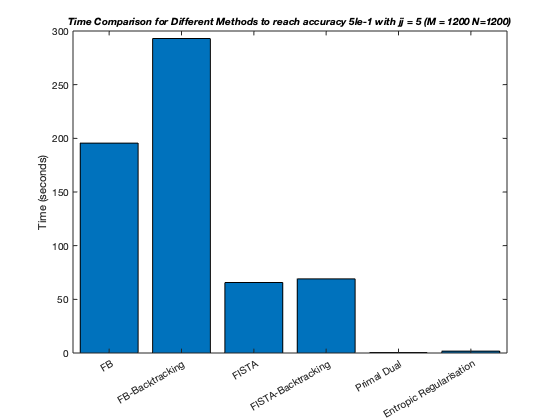

temp_fb = cell2mat(struct2cell(load('Results/jj5/FB-Tempjj=5.mat')));
temp_fbb = cell2mat(struct2cell(load('Results/jj5/FBbacktrack-Temp.mat')));
temp_fi = cell2mat(struct2cell(load('Results/jj5/Fista-Tempjj=5.mat')));
temp_fib = cell2mat(struct2cell(load('Results/jj5/Fistawbacktrack-Tempjj=5.mat')));
temp_pd = cell2mat(struct2cell(load('Results/jj5/Primaldual-Tempjj=5.mat')));
temp_er = cell2mat(struct2cell(load('Results/jj5/Entropicreg-Tempjj=5.mat')));

tempcrit_fb = cell2mat(struct2cell(load('Results/jj5/FB-Tempcrit_jj=5.mat')));
tempcrit_fbb = cell2mat(struct2cell(load('Results/jj5/FBbacktrack-Tempcrit.mat')));
tempcrit_fi = cell2mat(struct2cell(load('Results/jj5/Fista-Tempcritjj=5.mat')));
tempcrit_fib = cell2mat(struct2cell(load('/Users/conorosborne/Documents/GitHub/Code/FB/Results/jj5/Fistawbacktrack-Tempcritjj=5.mat', 'tempcrit_fib')));
tempcrit_pd = cell2mat(struct2cell(load('Results/jj5/Primaldual-Tempcritjj=5.mat')));
tempcrit_er = cell2mat(struct2cell(load('Results/jj5/Entropicreg-Tempcritjj=5.mat')));

%X = categorical({'FB', 'FB-Backtracking', 'FISTA', 'FISTA-Backtracking', 'Primal Dual', 'Linear Programming', 'Entropic Regularisation'});
%X = reordercats(X,{'FB', 'FB-Backtracking', 'FISTA', 'FISTA-Backtracking', 'Primal Dual', 'Linear Programming', 'Entropic Regularisation'});
%Y = [temp_pd temp_fbb temp_fi temp_fib temp_pd temp_lp temp_er];


X = categorical({'FB', 'FB-Backtracking', 'FISTA', 'FISTA-Backtracking', 'Primal Dual', 'Entropic Regularisation'});
X = reordercats(X,{'FB', 'FB-Backtracking', 'FISTA', 'FISTA-Backtracking', 'Primal Dual', 'Entropic Regularisation'});
Y = [tempcrit_fb(1) tempcrit_fbb(1) tempcrit_fi(1) tempcrit_fib(1) tempcrit_pd(1) tempcrit_er(1)];
bar(X,Y)
t = title('Time Comparison for Different Methods to reach accuracy 5le-1 with jj = 5 (M = 1200 N=1200)');
t.FontSize = 10;
t.FontAngle = 'italic';
ylabel('Time (seconds)');

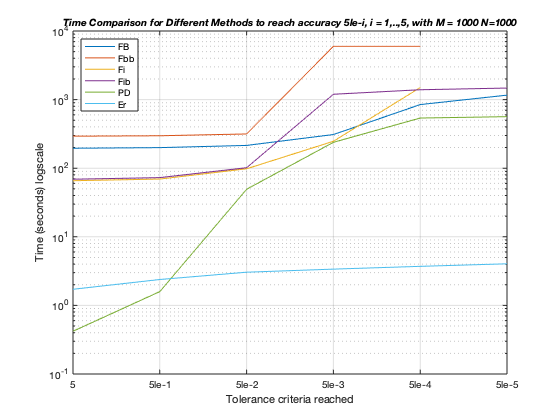

x_5= [1:5];
x = [1:6];
y1 = tempcrit_fb(1:6);

y2 = tempcrit_fbb(1:5);

y3 = (tempcrit_fi(1:5));

y4 = (tempcrit_fib(1:6));

y5 = tempcrit_pd(1:6);

y6 = tempcrit_er(1:6);

semilogy(x,y1,x_5,y2,x_5,y3,x,y4,x,y5,x,y6)

xticks([1:6])
xticklabels({'5','5le-1','5le-2','5le-3', '5le-4','5le-5'})

t = title('Time Comparison for Different Methods to reach accuracy 5le-i, i = 1,..,5, with M = 1000 N=1000');
t.FontSize = 10;
t.FontAngle = 'italic';
xlabel('Tolerance criteria reached')
ylabel('Time (seconds) logscale')
legend('FB','Fbb','Fi', 'Fib', 'PD', 'Er','Location','northwest')
grid on